clear
close all

dt = 0.075;
H_s = tf(2,[1 2 1]);
H_z = c2d(H_s,dt);
ts = 5;
ksi = 0.9;
wn = -(log(0.02)/(ksi*ts));
ro = 5;

s = roots([1 ksi*wn wn^2]);
z = exp(s*dt);
Ac_z = conv([1, -z(1)], [1, -z(2)]);
% a = 0.999;
a = 0;
% a = -0.999;
Ao_z = [1 2*a a*a];
A = conv([1,-1],H_z.den{1});
B = H_z.num{1};
[R_z, S_z, T_z] = RST(A, B, Ac_z, Ao_z)

R_z =     1.0000   -0.5337   -0.4663


S_z =    84.1507 -162.5935   78.8380


T_z =     0.3953         0         0


syms z
Hz = poly2sym(H_z.num{1}, z) / poly2sym(H_z.den{1}, z);
Hzinv = subs(Hz, z, 1/z);
lrr = Hz * Hzinv / ro + 1;
lrr_roots = vpa(solve(lrr))

$$lrr\_roots = \left(\begin{array}{c} 0.92161208819811471222583981466625-0.028584950752935587543976913918818\,\mathrm{i}\\ 0.92161208819811471222583981466625+0.028584950752935587543976913918818\,\mathrm{i}\\ 1.0840123839636611528914390554477-0.033621998895171332064164588394618\,\mathrm{i}\\ 1.0840123839636611528914390554477+0.033621998895171332064164588394618\,\mathrm{i} \end{array}\right)$$

abs(lrr_roots)

$$ans = \left(\begin{array}{c} 0.92205528062174088068878085028595\\ 0.92205528062174088068878085028595\\ 1.0845336727812036162825035727265\\ 1.0845336727812036162825035727265 \end{array}\right)$$

z2 = [sym2poly(lrr_roots(1)) sym2poly(lrr_roots(2))];
Ac_z2 = conv([1, -z2(1)], [1, -z2(2)]);
[R_z2, S_z2, T_z2] = RST(A, B, Ac_z2, Ao_z)

R_z2 =     1.0000   -0.5096   -0.4904


S_z2 =    97.5139 -179.7674   82.9202


T_z2 =     0.6667         0         0


controls_sim = sim("controls");

error_1 = controls_sim.Error(:,2);
error_2 = controls_sim.Error(:,3);
time = controls_sim.Output(:,1);

IAE1 = 0;
ITAE1 = 0;
IAE2 = 0;
ITAE2 = 0;

for i = 1:(20/dt)
    error_abs_ist1 = abs(error_1(i));
    IAE1 = IAE1 + error_abs_ist1;
    ITAE1 = ITAE1 + time(i) * error_abs_ist1;
    error_abs_ist2 = abs(error_2(i));
    IAE2 = IAE2 + error_abs_ist2;
    ITAE2 = ITAE2 + time(i) * error_abs_ist2;
end

IAE1 = IAE1 * dt

IAE1 = 0.3133

ITAE1 = ITAE1 * dt

ITAE1 = 0.5322

IAE2 = IAE2 * dt

IAE2 = 0.1379

ITAE2 = 0.0359

ITAE2 = ITAE2 * dt

Utilizaremos o Método LRR

controls_pert_entrada_sim = sim("controls_pert_entrada.slx");

out_p_ent = controls_pert_entrada_sim.Output(:,2);
Amp_max = max(out_p_ent)-out_p_ent(end)

Amp_max = 0.0186

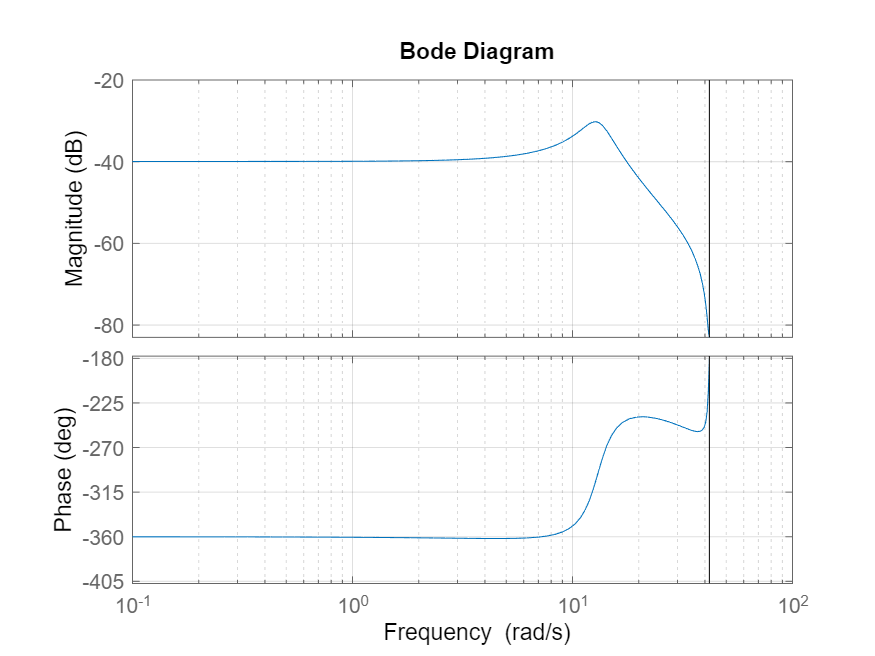

y_v = feedback(H_z, S_z2 / R_z2);
bode(y_v); grid on;

K = 0.01 p/ 10^-1

load dados_ruido.mat

ruido_ts = timeseries(ruido, tempo);
noise = resample(ruido_ts, time);

controls_pert_saida_sim = sim("controls_pert_saida.slx");

out_p_saida = controls_pert_saida_sim.Output(:,2);
noise_p_saida = controls_pert_saida_sim.Output(:,3);
control_p_saida = controls_pert_saida_sim.ControlAction(:,2);
abs_mean_control = mean(abs(control_p_saida))

abs_mean_control = 5.6433

abs_mean_noise = mean(abs(noise_p_saida))

abs_mean_noise = 0.0241

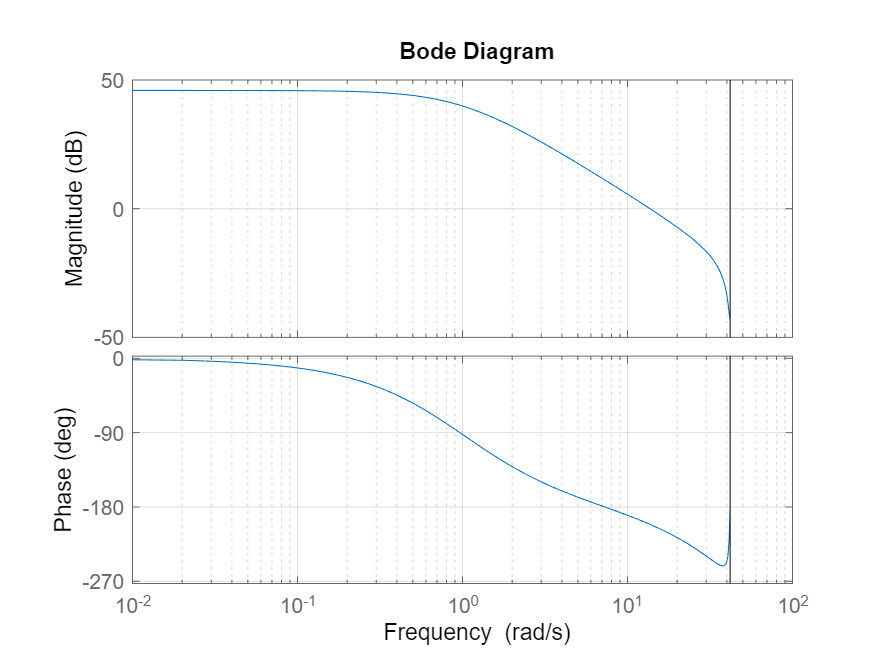

x_n = S_z2 / R_z2 * H_z;
bode(x_n); grid on;

K = 1.85 p/ 10 rad/s

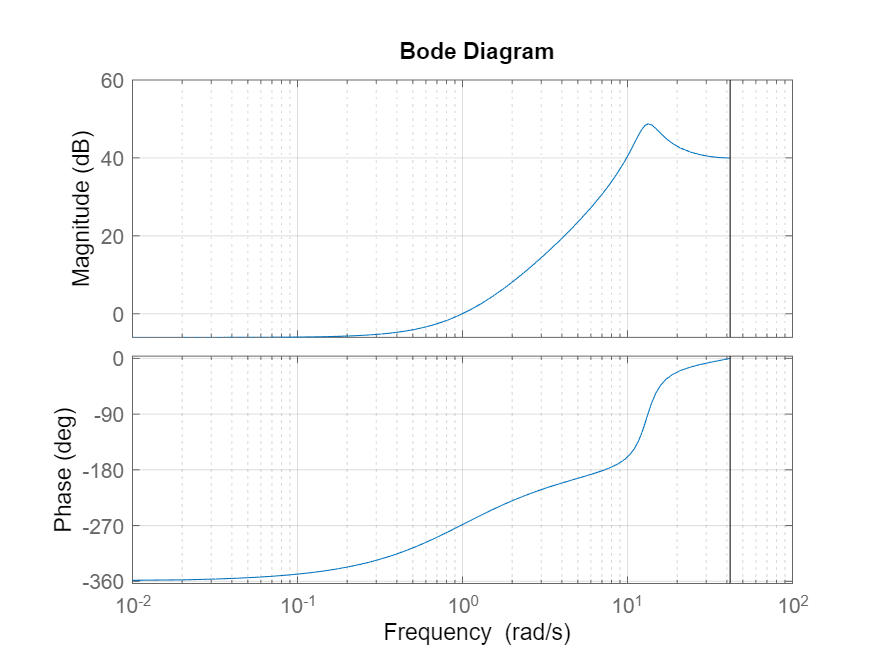

u_n = feedback(S_z2 / R_z2, H_z);
bode(u_n); grid on;

K = 117.085 p/ 10 rad/s